# Binary Frequency Shift Keying (FSK)    

% Author Name : Atmanand Manoj Gauns
% Affiliation : Roll No.: 201104012
%               Branch : E&TC GCE
%               Year : TE Sem- 5 2021-22 

## Variables

clc;
clear;
fc=4;
fs=100*fc;
t=[0:1/fs:20];
A=10;

## Message Signal

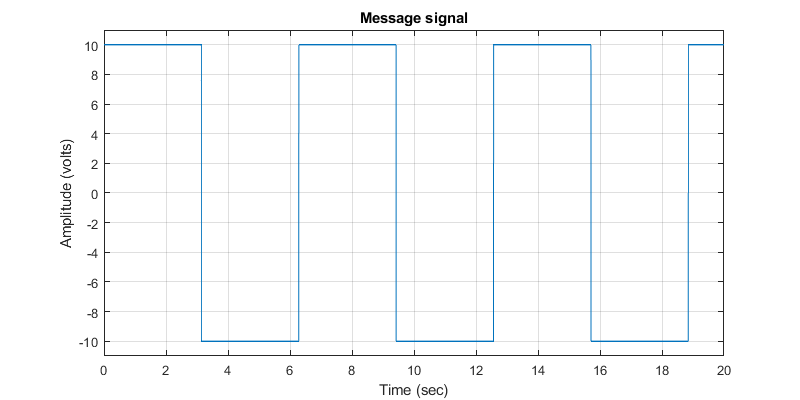

Vm=A.*square(t);
f1=figure;
plot(t,Vm);
xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Message signal');
ylim([-11.00 11.00])
set(f1,'Position',[0 0 800 400]);
grid on;

## Carrier Signal

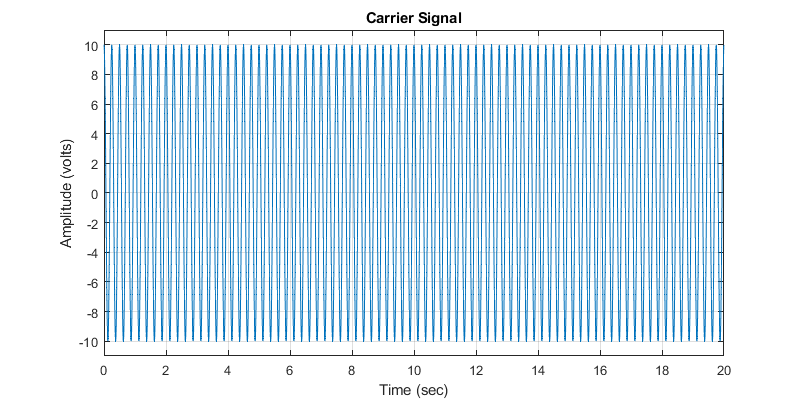

Vc=A.*cos(2.*pi.*fc.*t);
plot(t,Vc);
xlabel('Time (sec)');
ylabel('Amplitude (volts)');
title('Carrier Signal');
ylim([-11.00 11.00])
set(f1,'Position',[0 0 800 400]);
grid on;

## FSK Signal

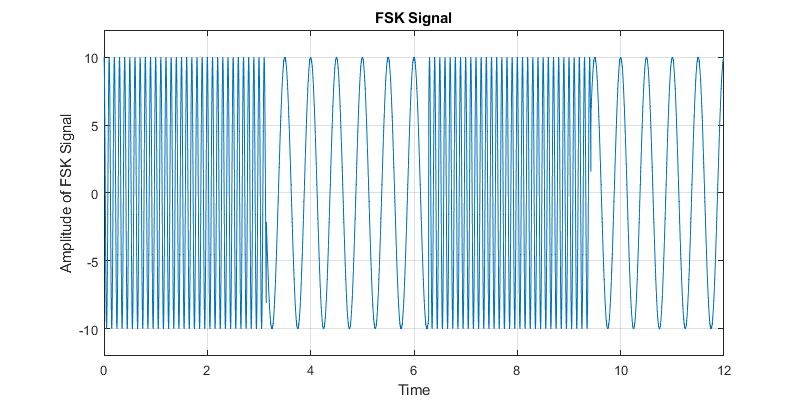

fd=0.6; %%frequency deviation
Vf=A.*cos(2.*pi.*(fc+Vm.*fd).*t);
plot(t,Vf);
xlabel("Time");
ylabel("Amplitude of FSK Signal");
title('FSK Signal');
ylim([-11.00 11.00])
set(f1,'Position',[0 0 800 400]);
grid on;

xlim([0 12])
ylim([-12 12])

## Frequency Spectrum of FSK Signal

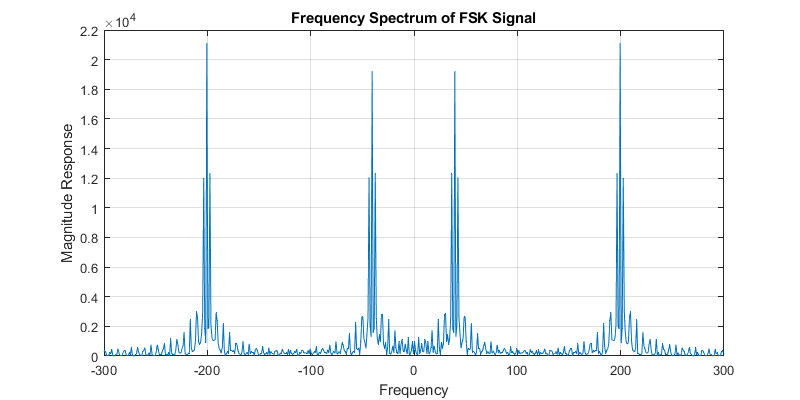

l=length(t);
i=(-l/2:1:l/2-1);  %% Frequency Index
plot(i,(fftshift(abs(fft(Vf)))));
xlabel("Frequency");
ylabel("Magnitude Response");
title('Frequency Spectrum of FSK Signal');
set(f1,'Position',[0 0 800 400]);
grid on;

xlim([-300 300])
ylim([0 22000])